# A comprehensive evaluation framewok and new similarity metrics to track blood pressure changes

This is the Matlab implementation of our paper "**A comprehensive evaluation framework and new similarity metrics to track blood pressure changes**" by *Shan He*, *Miodrag Bolic* from University of Ottawa.

**The main contributions of this paper:**

- This is the first paper demonstrates the limitation and drawbacks of the current evaluation standards for cuffless BP estimation studies, most of these standards employ distance metrics, such as mean difference (ME), mean absolute difference (MAD). And correlation coefficients, such as Pearson correlation coefficient. However, none of these metrics can accurately indicates how well the estimation model is in tracking BP patterns.

- This paper proposes new similarity metrics, the **distance**, **trend** metrics and the **composite **metric of both. With the proposed framework and metrics, the performance of a BP estimation model can be comprehensively evaluated, especially the ability in tracking BP pattern or changes. This method can be used to diagnose the problem of the estimation model for performance improvement.

Please refer to our paper for details of the proposed framework and metrics. In this MATLAB script, we will demonstate some examples of our methods.

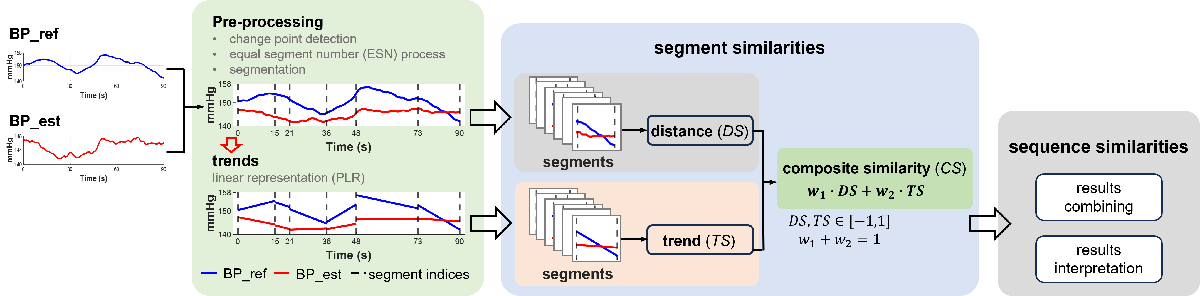

The framework of the porposed evaluation methods

## Pre-request

The proposed method employed a Bayesian method to detect change points of a sequence according to trend changes, to run the code shown below, please install "BEAST" matlab toolbox first and add to matlab path. Refer to [Bayesian Changepoint Detection & Time Series Decomposition - File Exchange - MATLAB Central (mathworks.com)](https://www.mathworks.com/matlabcentral/fileexchange/72515-bayesian-changepoint-detection-time-series-decomposition) for details.

## Data for demo

The reference BP and 5 different simulated BP estimations (shown in Figure 6) are demonstrated below.

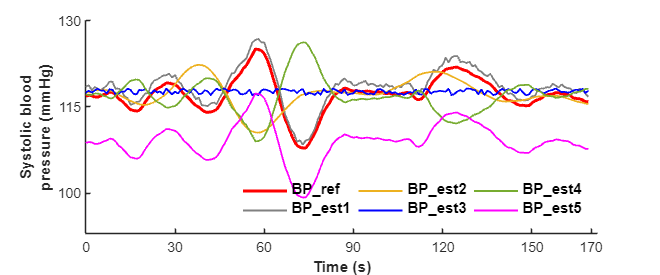

% load simulated dataset
bp_data = readtable('simulated_bp.csv');
bp_data = table2array(bp_data);

ref = bp_data(:,1); est = bp_data(:,2:end);

est1 = est(:,1); est2 = est(:,2); est3 = est(:,3); est4 = est(:,4); est5 = est(:,5);

t = [0:1:length(ref)-1]';
figure('Position',[100,100,600,250]); hold all; 
plot(t,ref,'LineWidth',2,'Color','r');
plot(t,est1,'LineWidth',1.2,'Color',[128 128 128]/255);
plot(t,est2,'LineWidth',1.2,'Color',"#EDB120");
plot(t,est3,'LineWidth',1.2,'Color',"b");
plot(t,est4,'LineWidth',1.2,'Color',"#77AC30");
plot(t,est5,'LineWidth',1.2,'Color',"m");
xlabel('Time (s)','FontSize',12,'FontWeight','bold'); ylabel({'Systolic blood','pressure (mmHg)'},'FontSize',12,'FontWeight','bold'); legend('BP ref','BP est1','BP est2','BP est3','BP est4','BP est5');
xticks([0,30,60,90,120,150,170]); xticklabels({'0','30','60','90','120','150','170'}); xlim([0 172]); ylim([93 130]);
legend({'BP\_ref','BP\_est1','BP\_est2','BP\_est3','BP\_est4','BP\_est5'},'Location','southeast','NumColumns',3,'FontSize',10,'FontWeight','bold'); legend('boxoff');
yticks([100,115,130]); yticklabels({'100','115','130'}); ax = gca; ax.XAxis.FontSize = 12; ax.YAxis.FontSize = 12;

## Apply the proposed methods to compare similarity between BP_est2 and BP_ref

- **1. Detect change points of BP_ref**

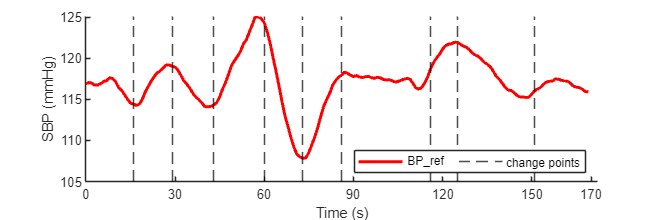

% detect change point for BP_ref using BEAST method
mcmc_samples = 1000000;
ref_beast = beast(ref,'season','none','print.options',false,'print.progress',false,'start',1,'deltat',1,'mcmc.samples',mcmc_samples);
ref_cp = ref_beast.trend.cp;
ref_cp = sort(ref_cp(~isnan(ref_cp)));

figure('Position',[100,100,600,200]); hold all; 
plot(t,ref,'LineWidth',2,'Color','r');
xline(ref_cp,'k--');
xlabel('Time (s)'); ylabel('SBP (mmHg)'); legend({'BP\_ref','change points'},'Location','southeast','NumColumns',2);
xticks([0,30,60,90,120,150,170]); xticklabels({'0','30','60','90','120','150','170'}); xlim([0 172]);

- **2. Detect change points of BP_est2**

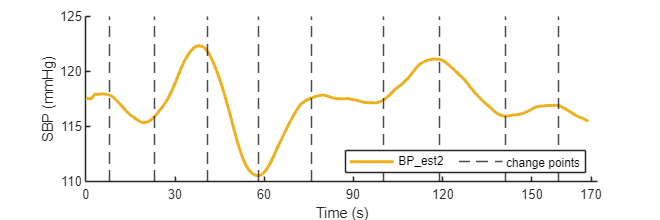

% detect change point for BP_est2 using BEAST method
mcmc_samples = 1000000;
est2_beast = beast(est2,'season','none','print.options',false,'print.progress',false,'start',1,'deltat',1,'mcmc.samples',mcmc_samples);
est2_cp = est2_beast.trend.cp;
est2_cp = sort(est2_cp(~isnan(est2_cp)));

figure('Position',[100,100,600,200]); hold all; 
plot(t,est2,'LineWidth',2,'Color',"#EDB120");
xline(est2_cp,'k--');
xlabel('Time (s)'); ylabel('SBP (mmHg)'); legend({'BP\_est2','change points'},'Location','southeast','NumColumns',2);
xticks([0,30,60,90,120,150,170]); xticklabels({'0','30','60','90','120','150','170'}); xlim([0 172]);

- **3. Combine the change points of reference and estimation and divide the sequences into segments**

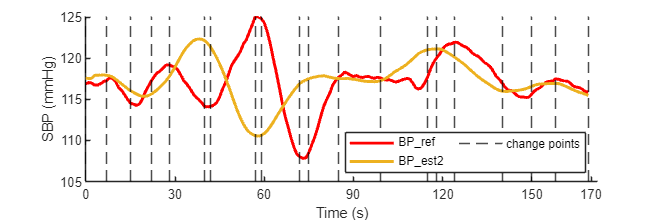

ref_est2_cp = sort(unique([1;ref_cp; est2_cp; length(ref)]));
figure('Position',[100,100,600,200]); hold all; 
plot(t,ref,'LineWidth',2,'Color','r');
plot(t,est2,'LineWidth',2,'Color',"#EDB120");
xline(ref_est2_cp-1,'k--');
xlabel('Time (s)'); ylabel('SBP (mmHg)'); legend({'BP\_ref','BP\_est2','change points'},'Location','southeast','NumColumns',2);
xticks([0,30,60,90,120,150,170]); xticklabels({'0','30','60','90','120','150','170'}); xlim([0 172]);

It can be observed that some segments are very short, for example, the segment 2 and segment 7 and segment 9, these segments may not have enough samples to approximate linear trend, since least squares requires at least 2 samples. Therefore, an additional process required to ensure each segment have enough samples (see **function** *change_pt_process*).

The ***change_pt_process*** will process the segment start and end points according to the input parameter "min_interval" which determines the minimal number of samples a segment should have (can be adjusted). For example, by setting min_interval=4 and the segmentation result is shown below.

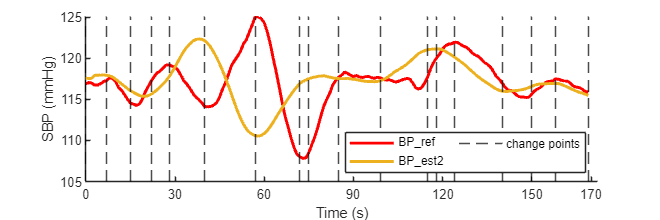

% reprocess the change points such that each segment has enough data
% samples (n>2) to approximate linear trend using least squares
min_interval = 4;
ref_est2_cp = change_pt_process(ref_est2_cp,4);

figure('Position',[100,100,600,200]); hold all; 
plot(t,ref,'LineWidth',2,'Color','r');
plot(t,est2,'LineWidth',2,'Color',"#EDB120");
xline(ref_est2_cp-1,'k--');
xlabel('Time (s)'); ylabel('SBP (mmHg)'); legend({'BP\_ref','BP\_est2','change points'},'Location','southeast','NumColumns',2);
xticks([0,30,60,90,120,150,170]); xticklabels({'0','30','60','90','120','150','170'}); xlim([0 172]);

It can be seen that all segments now have enough samples for linear trend approximation.

- **4. Approximate segment linear trend for both reference and estimation**

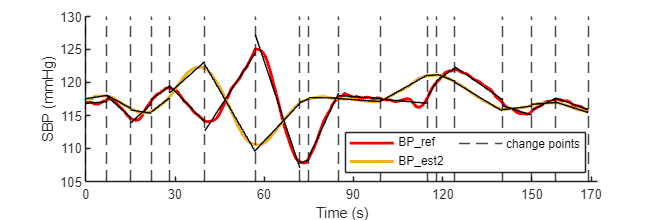

figure('Position',[100,100,600,200]); hold all; 
plot(t,ref,'LineWidth',2,'Color','r');
plot(t,est2,'LineWidth',2,'Color',"#EDB120");
xline(ref_est2_cp-1,'k--');

for i = 1:length(ref_est2_cp)-1
    st = ref_est2_cp(i); nd = ref_est2_cp(i+1);

    ref_seg = ref(st:nd); est2_seg = est2(st:nd);

    % approximate segment linear trend
    x_idx = double([st:1:nd]');
    ref_line = linear_trend(x_idx,ref_seg);
    est2_line = linear_trend(x_idx,est2_seg);
    plot(x_idx-1,ref_line,'k');
    plot(x_idx-1,est2_line,'k');
end
xlabel('Time (s)'); ylabel('SBP (mmHg)'); legend({'BP\_ref','BP\_est2','change points'},'Location','southeast','NumColumns',2);
xticks([0,30,60,90,120,150,170]); xticklabels({'0','30','60','90','120','150','170'}); xlim([0 172]);

- **5. Calculate segment similarity metrics using the proposed methods**

The composite similarity combines both distance and trend similarity using the weighted sum. In our paper, we assigned the weight of 0.6 to the distance similarity and 0.4 to the trend similarity (can be adjusted to your needs).

ref_est2_plr = [];
for i = 1:length(ref_est2_cp)-1
    st = ref_est2_cp(i); nd = ref_est2_cp(i+1);

    ref_seg = ref(st:nd); est2_seg = est2(st:nd);

    % approximate segment linear trend
    x_idx = double([st:1:nd]');
    ref_line = linear_trend(x_idx,ref_seg);
    est2_line = linear_trend(x_idx,est2_seg);
    
    ref_est2_plr = [ref_est2_plr;[i.*ones(length(ref_seg),1),x_idx,ref_seg,est2_seg,ref_line,est2_line]];
end

% move ref_plr and est_plr such that they have a same mean
ref_est2_plr(:,end) = ref_est2_plr(:,end)-(mean(ref_est2_plr(:,end))-mean(ref_est2_plr(:,end-1)));
max_plr = max([ref_est2_plr(:,end-1);ref_est2_plr(:,end)]); 
min_plr = min([ref_est2_plr(:,end-1);ref_est2_plr(:,end)]); 

seg_num = length(unique(ref_est2_plr(:,1)));
seg_ind = unique(ref_est2_plr(:,1));
ref_est2_res = [];
for i = 1:seg_num
    seg_idx = find(ref_est2_plr(:,1)==seg_ind(i));
    seg_data = ref_est2_plr(seg_idx,:);

    % calculate segment distance similarity
    seg_mae = mean(abs(seg_data(:,3)-seg_data(:,4)));
    seg_dist_sim = sigmoid_f(seg_mae,2.2,5.5);

    % calculate segment trend similarity
    seg_len = seg_data(end,2)-seg_data(1,2);
    seg_trend_sim = angle_similarity(seg_data(:,5),seg_data(:,6),max_plr,min_plr,seg_len);

    % calculate composite similarity
    seg_composite_sim = 0.6*seg_dist_sim+0.4*seg_trend_sim;

    ref_est2_res = [ref_est2_res;[seg_mae,seg_dist_sim,seg_trend_sim,seg_composite_sim,seg_len]];
end

ref_est2_result = array2table(ref_est2_res,'VariableNames',{'segment MAD','segment distance similarity','segment trend similarity','segment composite similarity','segment length'},'RowName',{'seg 1','2','3','4','5','6','7','8','9','10','11','12','13','14','15','16','17'});
disp(ref_est2_result);

             segment MAD    segment distance similarity    segment trend similarity    segment composite similarity    segment length
             ___________    ___________________________    ________________________    ____________________________    ______________

    seg 1      0.83125                0.99993                       0.96737                       0.98691                     7      
    2             0.74                0.99994                       0.85824                       0.94326                     8      
    3           1.1262                0.99987                      -0.23557                       0.50569                     7      
    4           1.8186                0.99939                        0.9849                        0.9936                     6      
    5           4.2831                0.87134                      -0.55857                       0.29937                    12      
    6           7.0661               -0.93819                

- **6. Calculate the temporally normalized results from segments for entire sequence comparison**

for i = 1:3
    ref_est2_tn(1,i) = sum(ref_est2_res(:,1+i).*ref_est2_res(:,end))/sum(ref_est2_res(:,end));
end
ref_est2_tn_result = array2table(ref_est2_tn,'VariableNames',{'TN_DS','TN_TS','TN_CS',},'RowName',{'Temporally normalized results'});
disp(ref_est2_tn_result);

                                      TN_DS      TN_TS      TN_CS 
                                     _______    _______    _______

    Temporally normalized results    0.57764    0.14807    0.40581



We created a function that includes all the step shown above, please check "***bp_similarity***". 

The **input** of this function should be:

- ref: the reference measurement, dimension of Nx1 (N: number of samples)

- est: the estimations, can be multiple different estimations using different approaches, dimension of Nxm (N:number of samples, m: number of estimations and m>=1)

- mcmc_samples: number of mcmc sampling for change point detection using Bayesian method. In our experiment, we set mcmc_samples=1000000

- min_interval: the minimum number of samples that a segment should have >=2

- w1: the weight of distance similarity when calculating compiste similarity using weighted sum, w1+w2=1

- w2: the weight of trend similarity when calculating compiste similarity using weighted sum, w1+w2=1

The **output** of this function should be:

- ref_est_cp: processed change points for segmentation

- ref_est_plr: column1: the segment index, column2: the x-axis value of each segment, column3: the original reference segment, column4: the original estimated segment, column5: the approximated linear trend for reference, column6: the approximated linear trend for estimation

- ref_est_seg_sim: the segment similarity between reference and estimation. column1: segment MAD; column2: segment distance similarity; column3: segment trend similarity; column4: segment composite similarity; column5: segment duration

- ref_est_tn_sim: the temporally normalizaed similarities for entire sequence comparison. column1: temporally normalized distance similarity; column2: temporally normalized trend similarity; column1: temporally normalized composite similarity;

And an example of the "***bp_similarity***" function to compare the similarity between BP_est1 to BP_est5 and BP_ref is shown below.

## Example of comparing similarity between BP_est1-5 and BP_ref using the proposed method (***bp_similarity***)

mcmc_samples = 1000000; min_interval = 5; w1 = 0.6; w2 = 0.4;
[ref_est_cp,ref_est_plr,ref_est_seg_sim,ref_est_tn_sim] = bp_similarity(ref,[est1,est2,est3,est4,est5],mcmc_samples,min_interval,w1,w2);

## Check the results (BP_ref vs BP_est4)

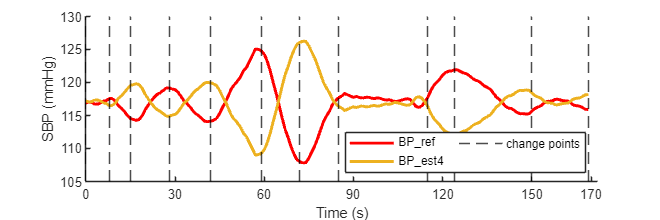

% 1. check the detected change points
ref_est4_cp = ref_est_cp{1,4}; % this is the change point which starts from 1, convert to time index which start from 0, and just subtract 1
figure('Position',[100,100,600,200]); hold all; 
plot(t,ref,'LineWidth',2,'Color','r');
plot(t,est4,'LineWidth',2,'Color',"#EDB120");
xline(ref_est4_cp-1,'k--');
xlabel('Time (s)'); ylabel('SBP (mmHg)'); legend({'BP\_ref','BP\_est4','change points'},'Location','southeast','NumColumns',2);
xticks([0,30,60,90,120,150,170]); xticklabels({'0','30','60','90','120','150','170'}); xlim([0 172]);

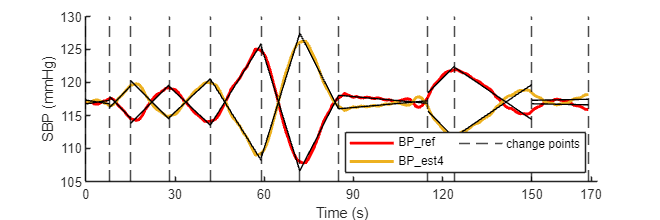

% 2. chcek the approximated PLR (approximated segment linear trend)
ref_est4_plr = ref_est_plr{1,4};
seg_ind = unique(ref_est4_plr(:,1));

figure('Position',[100,100,600,200]); hold all; 
plot(t,ref,'LineWidth',2,'Color','r');
plot(t,est4,'LineWidth',2,'Color',"#EDB120");
xline(ref_est4_cp-1,'k--');

for i = 1:length(seg_ind)
    seg_idx = find(ref_est4_plr(:,1)==seg_ind(i));
    seg_data = ref_est4_plr(seg_idx,:);
    seg_ref_t = seg_data(:,2)-1;
    seg_ref_plr = seg_data(:,5);
    seg_est_plr = seg_data(:,6);
    plot(seg_ref_t,seg_ref_plr,'k');
    plot(seg_ref_t,seg_est_plr,'k');
end
xlabel('Time (s)'); ylabel('SBP (mmHg)'); legend({'BP\_ref','BP\_est4','change points'},'Location','southeast','NumColumns',2);
xticks([0,30,60,90,120,150,170]); xticklabels({'0','30','60','90','120','150','170'}); xlim([0 172]);

% 3. check segment similarities
ref_est4_seg_sim = ref_est_seg_sim{1,4};
ref_est4_seg_sim = array2table(ref_est4_seg_sim,'VariableNames',{'segment MAD','segment distance similarity','segment trend similarity','segment composite similarity','segment length'},'RowName',{'seg 1','2','3','4','5','6','7','8','9','10','11'});
disp(ref_est4_seg_sim);

             segment MAD    segment distance similarity    segment trend similarity    segment composite similarity    segment length
             ___________    ___________________________    ________________________    ____________________________    ______________

    seg 1      0.42667                0.99997                     -0.074029                       0.57037                     8      
    2           2.1725                0.99868                      -0.42933                       0.42748                     7      
    3           3.3886                0.98097                      -0.51269                       0.38351                    13      
    4           3.4533                0.97808                      -0.53977                       0.37094                    14      
    5           7.8089               -0.98763                      -0.89922                      -0.95227                    17      
    6           10.716               -0.99998                

% 4. check temporally normalized similarities for entire sequence
% comparison
ref_est4_tn = ref_est_tn_sim{1,4};
ref_est4_tn_result = array2table(ref_est4_tn,'VariableNames',{'TN_DS','TN_TS','TN_CS',},'RowName',{'Temporally normalized results'});
disp(ref_est4_tn_result);

                                      TN_DS      TN_TS       TN_CS  
                                     _______    ________    ________

    Temporally normalized results    0.34513    -0.46039    0.022923



% display the temporally normalized (TN) similarity for BP_est1-5 and BP_ref
ref_est_tn(1,:) = ref_est_tn_sim{1,1};
ref_est_tn(2,:) = ref_est_tn_sim{1,2};
ref_est_tn(3,:) = ref_est_tn_sim{1,3};
ref_est_tn(4,:) = ref_est_tn_sim{1,4};
ref_est_tn(5,:) = ref_est_tn_sim{1,5};
ref_est_tn_result = array2table(ref_est_tn,'VariableNames',{'distance similarity (TN)','trend similarity (TN)','composite similarity (TN)',},'RowName',{'BP_est1 vs BP_ref','BP_est2 vs BP_ref','BP_est3 vs BP_ref','BP_est4 vs BP_ref','BP_est5 vs BP_ref'});
disp(ref_est_tn_result);

                         distance similarity (TN)    trend similarity (TN)    composite similarity (TN)
                         ________________________    _____________________    _________________________

    BP_est1 vs BP_ref             0.99977                   0.97427                    0.98957         
    BP_est2 vs BP_ref             0.56405                   0.16549                    0.40462         
    BP_est3 vs BP_ref             0.80809                   0.33662                     0.6195         
    BP_est4 vs BP_ref             0.34513                  -0.46039                   0.022923         
    BP_est5 vs BP_ref            -0.99391                   0.98194                   -0.20357         



function cp_new = change_pt_process(change_pt,min_interval)
while true
    cp_diff = diff(change_pt)+1;
    idx = find(cp_diff<min_interval);
    if length(idx)==0
        cp_new = change_pt;
        break;
    else
        idx1 = idx(1); idx2 = idx(1)+1;
        if idx1==1 
            cp_new = [1; change_pt(idx2+1:end)];
            
        elseif idx2==length(change_pt)
            cp_new = [change_pt(1:idx1-1); change_pt(idx2)];
        else
            cp_new = [change_pt(1:idx1); change_pt(idx2+1:end)];
        end
    end
    change_pt = [];
    change_pt = cp_new;
end
end

function line = linear_trend(x,ts)
% input: x: x-axis data, ts: time series data
% output: the linear trend using robust linear regression (least squares
% method)
f = fit(x,ts,'poly1');
line = x.*f.p1+f.p2;
end

function sig_out = sigmoid_f(x,c1,c2)
sig_out = 2*(-1./(1+exp(-c1*(x-c2))))+1;
end

function trend_sim = angle_similarity(ts1_line,ts2_line,max_val,min_val,seg_len)
ts1_slope = (ts1_line(end)-ts1_line(1))/seg_len; ts2_slope = (ts2_line(end)-ts2_line(1))/seg_len;
if ts1_slope*ts2_slope>=0
    if ts1_slope>=0 && ts2_slope>=0
        min_st = min([ts1_line(1),ts2_line(1)]);
        max_angle = atand((max_val-min_st)/seg_len);
        ts1_sp = abs(ts1_slope); ts2_sp = abs(ts2_slope);
        ts1_ang = atand(ts1_sp); ts2_ang = atand(ts2_sp);
        ts12_angle_diff = abs(ts1_ang-ts2_ang);
        trend_sim = 1-ts12_angle_diff/max_angle;
    elseif ts1_slope<=0 && ts2_slope<=0
        max_st = max([ts1_line(1),ts2_line(1)]);
        max_angle = atand((max_st-min_val)/seg_len);
        ts1_sp = abs(ts1_slope); ts2_sp = abs(ts2_slope);
        ts1_ang = atand(ts1_sp); ts2_ang = atand(ts2_sp);
        ts12_angle_diff = abs(ts1_ang-ts2_ang);
        trend_sim = 1-ts12_angle_diff/max_angle;
    end
else
    if ts1_slope<0 && ts2_slope>0
        max_angle1 = atand((ts1_line(1)-min_val)/seg_len);
        max_angle2 = atand((max_val-ts2_line(1))/seg_len);
        ts1_sp = abs(ts1_slope); ts2_sp = abs(ts2_slope);
        ts1_ang = atand(ts1_sp); ts2_ang = atand(ts2_sp);
        ts12_angle_diff = abs(ts1_ang+ts2_ang);
        trend_sim = -ts12_angle_diff/(max_angle1+max_angle2);
    elseif ts1_slope>0 && ts2_slope<0
        max_angle1 = atand((max_val-ts1_line(1))/seg_len);
        max_angle2 = atand((ts2_line(1)-min_val)/seg_len);
        ts1_sp = abs(ts1_slope); ts2_sp = abs(ts2_slope);
        ts1_ang = atand(ts1_sp); ts2_ang = atand(ts2_sp);
        ts12_angle_diff = abs(ts1_ang+ts2_ang);
        trend_sim = -ts12_angle_diff/(max_angle1+max_angle2);
    end
end
end

function [ref_est_cp,ref_est_plr,ref_est_seg_sim,ref_est_tn_sim] = bp_similarity(ref,est,mcmc_samples,min_interval,w1,w2)
% input: ref - the reference measurement of BP, prefer a Nx1 array
% input: est - the estimation of BP, can be multiple (m) estimations, prefer
% Nxm array
% input: mcmc_samples - amount of mcmc sampling for bayesian change point
% detection, can be adjusted, a larger amount is preferred but will add
% more running time
% input: min_interval - minimal samples for one segment, should be greater
% than 2 samples
% input: w1 - weight for distance similarity
% input: w2 - weight for trend similarity

% output: seg_res - a cell with dimension of 1xm, and each cell includes
% the segment similarities and the composite score using temporal
% normalization (the last row)

% Step1: detect change points and segment reference BP according to trend
% changes using a Bayesian (BEAST) method
ref_beast = beast(ref,'season','none','print.options',false,'print.progress',false,'start',1,'deltat',1,'mcmc.samples',mcmc_samples);
ref_cp = ref_beast.trend.cp; ref_cp = ref_cp(~isnan(ref_cp)); % extract change points and remove NaN values for reference BP

num_est = size(est,2); % how many estimations included
ref_est_cp = {};
ref_est_plr = {};
ref_est_seg_sim = {};
ref_est_tn_sim = {};
for i = 1:num_est
    re_cp = [];
    % Step2: detect change points and segment estimated BP according to trend
    % changes using a Bayesian (BEAST) method
    est_beast = beast(est(:,i),'season','none','print.options',false,'print.progress',false,'start',1,'deltat',1,'mcmc.samples',mcmc_samples);
    est_cp = est_beast.trend.cp; est_cp = est_cp(~isnan(est_cp)); % extract change points and remove NaN values for estmated BP (the detected change points using BEAST may include NaN)
    re_cp = sort(unique([1;ref_cp;est_cp;length(ref)])); % merge the change points of reference and estimated BP and along with start and end points of the sequence
    
    re_cp = change_pt_process(re_cp,min_interval); % process the change points and ensure each segment include enough points for linear trend representation using least squares
    ref_est_cp{1,i} = re_cp; % store the processed change points of each pair of reference and estimated BPs
    
    % Step3: segment the reference and estimated BPs with the processed
    % change points and approximate linear trend for each segment with
    % least squares

    plr = [];

    for k = 1:length(re_cp)-1
        st = re_cp(k); nd = re_cp(k+1);
        ref_seg = []; est_seg = [];
        ref_seg = ref(st:nd,:);  est_seg = est(st:nd,i);
        % For each segment, apply least squares to approximate the linear
        % trend
        x_idx = double([st:1:nd]'); % the x index
        f1 = fit(x_idx,ref_seg,'poly1'); ref_line = x_idx.*f1.p1+f1.p2; % the approximated linear trend of reference segment
        f2 = fit(x_idx,est_seg,'poly1'); est_line = x_idx.*f2.p1+f2.p2; % the approximated linear trend of estimated segment
        ref_line = reshape(ref_line,[length(ref_seg),1]); est_line = reshape(est_line,[length(ref_seg),1]); 
        plr = [plr;k*ones(length(ref_seg),1),x_idx,ref_seg,est_seg,ref_line,est_line]; % store the approximated linear trends and original segments with segmemt index
    end
    % process the PLR for estimated BP such that it has the same mean to
    % the reference PLR
    ref_est_plr{1,i} = plr;

    plr(:,end) = plr(:,end)-(mean(plr(:,end))-mean(plr(:,end-1)));
    
    plr_max = max([plr(:,end-1);plr(:,end)]); plr_min = min([plr(:,end-1);plr(:,end)]); % get the maximum and minimum values of the reference PLR and estimated PLR for trend similarity comparison
    
    seg_id = [];
    seg_id = unique(plr(:,1));
    seg_result = [];
    for j = 1:length(seg_id)
        seg_idx = find(plr(:,1)==seg_id(j));
        seg_data = plr(seg_idx,:);

        % calculate segment mad and distance similarity
        seg_mad = mean(abs(seg_data(:,3)-seg_data(:,4))); % segment MAD
        seg_dist_sim = sigmoid_f(seg_mad,2.2,5.5); % segment distance similarity using the proposed method
        
        % calculate the trend similarity
        seg_len = seg_data(end,2)-seg_data(1,2);
        seg_trend_sim = angle_similarity(seg_data(:,5),seg_data(:,6),plr_max,plr_min,seg_len);

        % calculate segment composite similarity
        seg_composite_sim = w1*seg_dist_sim+w2*seg_trend_sim;

        % store the segment similarities
        seg_result = [seg_result;[seg_mad,seg_dist_sim,seg_trend_sim,seg_composite_sim,seg_len]];
    end
    % calculated temporally normalized metrics for entire sequence
    % comparison
    seg_tn_result = [];
    for j = 1:3
        seg_tn_result(1,j) = sum(seg_result(:,1+j).*seg_result(:,end))/sum(seg_result(:,end));
    end
    ref_est_seg_sim{1,i} = seg_result; 
    ref_est_tn_sim{1,i} = seg_tn_result;
end
end
